general linear least squares model

clear,clc,clf,format short g
%x and y are the table rows for the data provided
x =[1 2 3 4 5]'; y =[2.2 2.8 3.6 4.5 5.5]';
Z = [ones(size(x)) x 1./x];
a = (Z'*Z)\(Z'*y)

a =        0.3745
      0.98644
      0.84564


Sr = sum((y-Z*a).^2)

Sr =     0.0027651

r2 = 1-Sr/sum((y-mean(y)).^2)

r2 =        0.9996

syx = sqrt(Sr/(length(x)-length(a)))

syx =      0.037183

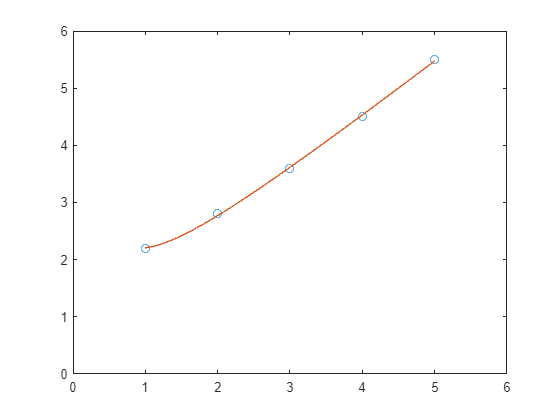

xp=[1:0.125:5];
%formula utilized is below, y = a + bx + c/x
yp=a(1)+a(2)*xp+a(3)./xp;
plot(x,y,'o',xp,yp)
xlim([0 6]),ylim([0 6])